%% clear cache
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "vaiueo2d.wav";
output_file_path = "D:/名城大学/研究室/演習/data/LPC/synthesized_signal_by_LPCVocoder.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path, output_file_path)

audio_file_manipulator =   AudioFileManipulator のプロパティ:

     input_file_path: "vaiueo2d.wav"
    output_file_path: "D:/名城大学/研究室/演習/data/LPC/synthesized_signal_by_LPCVocoder.wav"
              signal: []
         sample_rate: []
         information: []


audio_file_manipulator.load_properties();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : vaiueo2d.wav
output_file_path : D:/名城大学/研究室/演習/data/LPC/synthesized_signal_by_LPCVocoder.wav
signal shape : (17500, 1)
sample_rate: 22050 [Hz]
             Filename: 'D:\名城大学\研究室\演習\MatlabPractice\SourceCode\Analysis\STRAIGHT\STRAIGHTV40_007b\vaiueo2d.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 22050
         TotalSamples: 17500
             Duration: 0.7937
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16

--------------------------------------------



%% set LinearPredictiveCoding class parameters
start_point = 3728;  % あのスタート位置
continue_time = 32; % [ms]
continue_point = int32(continue_time * audio_file_manipulator.information.SampleRate / 1000);

%% generate LPCVocoder instance
lpc_vocoder = LinearPredictiveCodingVocoder(audio_file_manipulator.signal, audio_file_manipulator.information.SampleRate);
lpc_vocoder.display_properties();

----------------------------------------------
----------------- LPC Vocoder ----------------
signal size : (17500, 1)
window_mode : hamming
order : 30
threshold : 0.000100
internal_status size : (30, 1)
synthesized_signal size : (17500, 1)
impulse_response size : (17500, 1)
----------------------------------------------



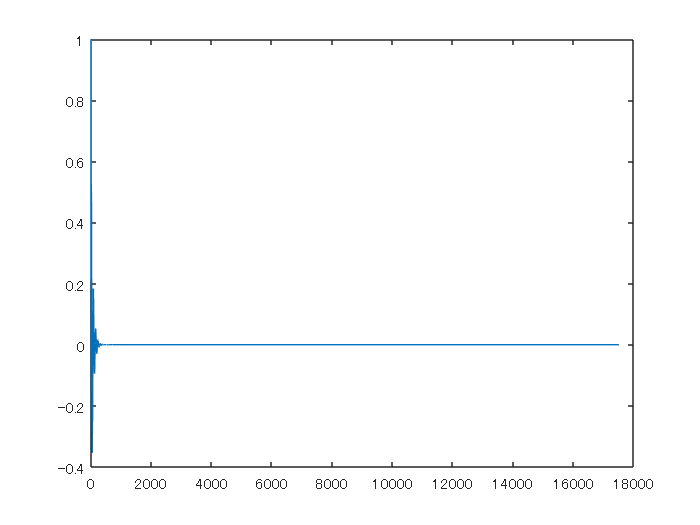

plot(lpc_vocoder.impulse_response);

soundsc(lpc_vocoder.synthesized_signal, audio_file_manipulator.information.SampleRate);
audio_file_manipulator.signal = lpc_vocoder.synthesized_signal;
audio_file_manipulator.normalize();
audio_file_manipulator.change_scale();
audio_file_manipulator.save_properties();